### `Ant-Colony OPtimization (ACO)`

`1. Load Data and Define ACO Parameters`

% Load the matrices from CSV files
% These matrices represent the distances and times between delivery locations
distanceMatrix = readmatrix('distance_matrix_adjusted.csv');
timeMatrix = readmatrix('time_matrix_adjusted.csv');

% Define ACO parameters
numAnts = 50; % Number of ants used in the algorithm
numIterations = 200; % Number of iterations for the ACO algorithm
alpha = 1; % Influence of pheromone
beta = 2; % Influence of distance
evaporationRate = 0.5; % Rate at which pheromone evaporates

% Define number of runs
% We will run the ACO algorithm multiple times to find the best route
numRuns = 10;

% Initialize arrays to store results of multiple runs
allBestRoutes = cell(numRuns, 1);  % Store best routes for each run
allBestDistances = zeros(numRuns, 1);  % Store best distances for each run
allBestTimes = zeros(numRuns, 1);  % Store best times for each run
overallBestRoute = [];  % Store the overall best route found
overallBestDistance = inf;  % Initialize best distance as infinity
overallBestTime = inf;  % Initialize best time as infinity

% Fix the random seed for reproducibility
% This ensures that the results are consistent across multiple runs
rng(1);

`2. Run ACO Multiple Times`

% Run ACO multiple times
for run = 1:numRuns
    % Call the ACO function to find the best route, distance, and time
    [bestRoute, bestDistance, bestTime] = aco(distanceMatrix, timeMatrix, numAnts, numIterations, alpha, beta, evaporationRate);
    allBestRoutes{run} = bestRoute;
    allBestDistances(run) = bestDistance;
    allBestTimes(run) = bestTime;

    % Update the overall best route if a better route is found
    if bestDistance < overallBestDistance
        overallBestDistance = bestDistance;
        overallBestRoute = bestRoute;
    end

    % Update the overall best time if a better time is found
    if bestTime < overallBestTime
        overallBestTime = bestTime;
        overallBestRoute = bestRoute;
    end
end

`3. Display Results`

% Display results
disp('Results from multiple runs:');

Results from multiple runs:


for run = 1:numRuns
    disp(['Run ', num2str(run), ' - Best Distance: ', num2str(allBestDistances(run)), ', Best Time: ', num2str(allBestTimes(run))]);
end

Run 1 - Best Distance: 107.1826, Best Time: 1286.05
Run 2 - Best Distance: 106.6615, Best Time: 1286.05
Run 3 - Best Distance: 102.0204, Best Time: 1286.05
Run 4 - Best Distance: 97.4356, Best Time: 1286.05
Run 5 - Best Distance: 106.1858, Best Time: 1286.05
Run 6 - Best Distance: 102.3239, Best Time: 1286.05
Run 7 - Best Distance: 97.5985, Best Time: 1286.05
Run 8 - Best Distance: 100.834, Best Time: 1286.05
Run 9 - Best Distance: 106.3094, Best Time: 1286.05
Run 10 - Best Distance: 100.3096, Best Time: 1286.05



% Display the overall best distance and time
disp(['Overall Best Distance: ', num2str(overallBestDistance)]);

Overall Best Distance: 97.4356


disp(['Overall Best Time: ', num2str(overallBestTime)]);

Overall Best Time: 1286.05


disp('Overall Best Route:');

Overall Best Route:


disp(overallBestRoute);

  Columns 1 through 26

     1     5     6     8    12    10    11    13    14    16    17    19    20    21    15     2     3     9    23    32    22    24    25    26    30    29

  Columns 27 through 32

    28    27    31    18     7     4



`4. Calculate and Display Statistics`

% Calculate statistics
meanDistance = mean(allBestDistances);
stdDistance = std(allBestDistances);
meanTime = mean(allBestTimes);
stdTime = std(allBestTimes);
disp(['Mean Distance: ', num2str(meanDistance)]);

Mean Distance: 102.6861


disp(['Standard Deviation of Distances: ', num2str(stdDistance)]);

Standard Deviation of Distances: 3.7194


disp(['Mean Time: ', num2str(meanTime)]);

Mean Time: 1286.05


disp(['Standard Deviation of Times: ', num2str(stdTime)]);

Standard Deviation of Times: 1.3127e-13


`5. Plot the Locations and Overall Best Route`

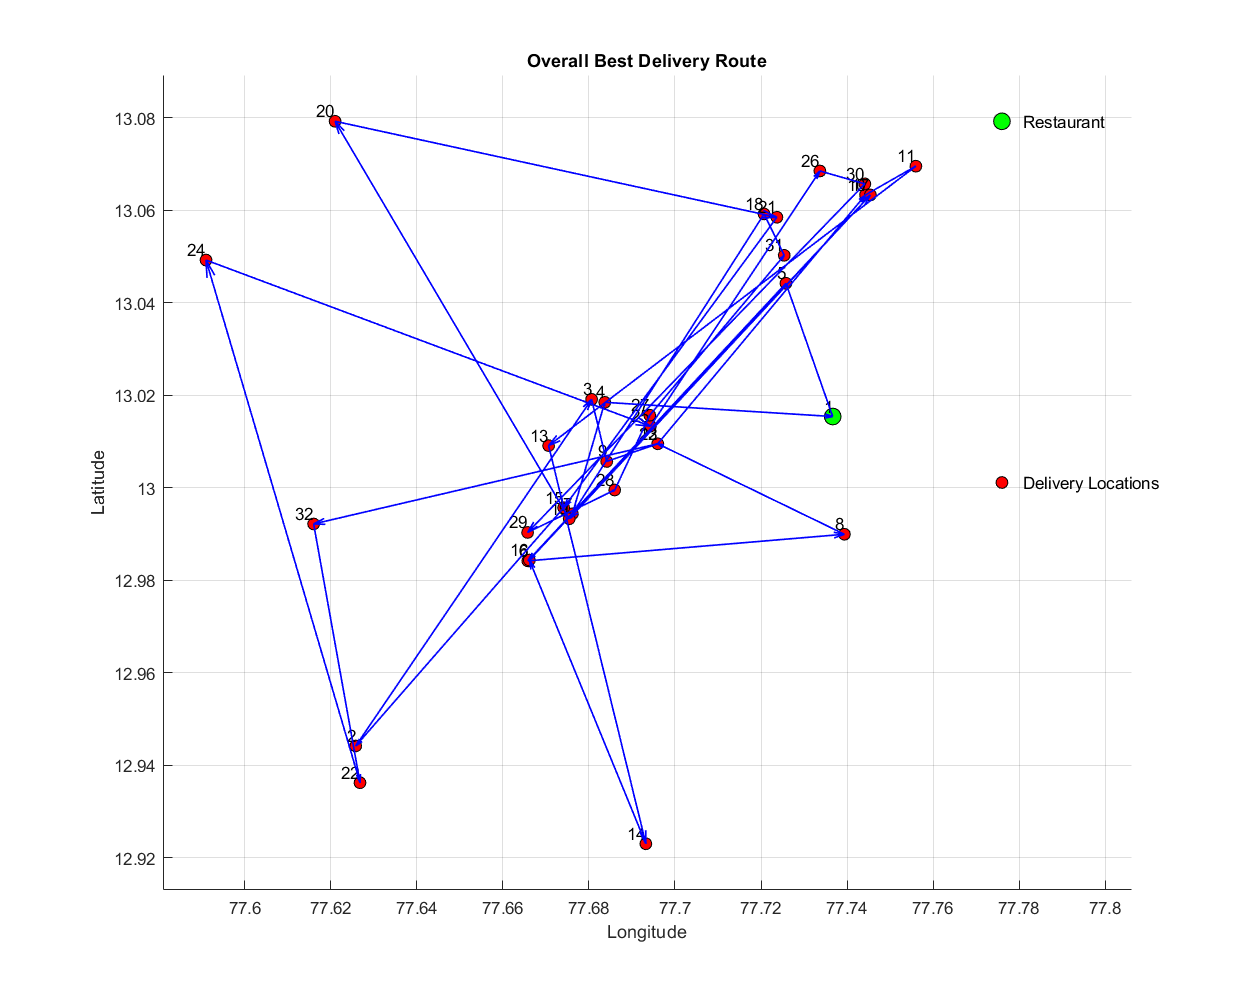

% Create a larger figure
figure('Position', [100, 100, 1000, 800]);  % Increase figure size
hold on;

% Plot all delivery locations
scatter(delivery_longitudes, delivery_latitudes, 50, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'r');

% Highlight the starting location 
scatter(delivery_longitudes(1), delivery_latitudes(1), 100, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'g');

% Label all delivery locations
text(delivery_longitudes, delivery_latitudes, num2str((1:numLocations)'), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

% Plot the route with arrows indicating direction
for i = 1:length(overallBestRoute)
    from = overallBestRoute(i);
    to = overallBestRoute(mod(i, length(overallBestRoute)) + 1);
    if from <= numLocations && to <= numLocations
        quiver(delivery_longitudes(from), delivery_latitudes(from), ...
               delivery_longitudes(to) - delivery_longitudes(from), ...
               delivery_latitudes(to) - delivery_latitudes(from), ...
               0, 'b', 'LineWidth', 1, 'MaxHeadSize', 0.1, 'AutoScale', 'off');
    end
end

% Enhance the plot
xlabel('Longitude');
ylabel('Latitude');
title('Overall Best Delivery Route');
grid on;

% Extend axis limits slightly
ax = gca;
xlim([min(delivery_longitudes) - 0.01, max(delivery_longitudes) + 0.05]);
ylim([min(delivery_latitudes) - 0.01, max(delivery_latitudes) + 0.01]);

% Add legend indicators
legend_x = max(delivery_longitudes) + 0.02;
legend_y = linspace(max(delivery_latitudes), min(delivery_latitudes), 3);

scatter(legend_x, legend_y(1), 100, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'g');
text(legend_x + 0.005, legend_y(1), 'Restaurant', 'VerticalAlignment', 'middle');

scatter(legend_x, legend_y(2), 50, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'r');
text(legend_x + 0.005, legend_y(2), 'Delivery Locations', 'VerticalAlignment', 'middle');

hold off;